# 論文の実装~Algorithm 2~

## MATLABの初期化処理

clear all;

## システムのダイナミクス


A = [-1 2; 2.2 1.7];
B = [2; 1.6]

B =     2.0000
    1.6000


C = [1 2];

sys = ss(A, B, C, [], 1)


sys =
 
  A = 
        x1   x2
   x1   -1    2
   x2  2.2  1.7
 
  B = 
        u1
   x1    2
   x2  1.6
 
  C = 
       x1  x2
   y1   1   2
 
  D = 
       u1
   y1   0
 
サンプル時間:  1 seconds
離散時間状態空間モデル。



% step(sys)

## 学習パラメータ

F = -1;
Q = 6;
R = 1;
gamma = 0.8;
learningFreq = 21;

K_0 = [0.3 1.3 0.75];
x_0 = [5; -5];
r_0 = [5];
X_0 = [x_0; r_0];

## その他変数宣言

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];
Q1 = C1'*Q*C1;

## 学習

% 初期化
X = X_0;
X_old = X_0;
K1 = K_0;
u = -K1*X;

count = 1;

yList = [C*x_0];
rList = [r_0];


for i = 1 : 60*21
    % 方策評価
    if i > 1
        x = X_old;
        dx = X;
        y = (x'*Q1*x + u'*R*u);
        num = size(Q1,1) + size(R,1);
        h1 = computeQuadraticBasis([x;u]);
        h2 = computeQuadraticBasis([dx;-K1*dx]);
        H = h1 - gamma* h2;
        if (count <= learningFreq)
            y_buf(count) = y;
            H_buf(count,:) = H;
            count = count + 1;
        else
            theta = (H_buf'*H_buf)\H_buf'*y_buf';
            count = 1;
            
            idx = 1;
            for j = 1 : size(X, 1)+1
                for k = j : size(X, 1)+1
                    H_hat(j, k) = theta(idx);
                    idx = idx + 1;
                end
            end
            H = (H_hat+H_hat')/2;
            Huu = H(size(Q1, 1)+1:end,size(Q1, 1)+1:end);
            Hux = H(size(Q1, 1)+1:end,1:size(Q1, 1));
            
            % 方策改善
            K1 = Huu\Hux;
        end
    end
   
%     for j = 1 : learningFreq
%         ZExp(:, j)'*H*ZExp(:,j) - (XExp(:,j)'*Q1*XExp(:,j)+uExp(:, j)'*R*uExp(:, j)+gamma*ZExp(:, j+1)'*H*ZExp(:,j+1))
%     end
    
    % 行動決定
    u = -K1*X;
    u = -K1*X+2*randn(1,1);
    
    
    % 状態遷移
    X_old = X;
    X = T * X + B1 * u;
    y = C * X(1:2);
    
    r = X(3);
    yList = [yList; y];
    rList = [rList; r];
end

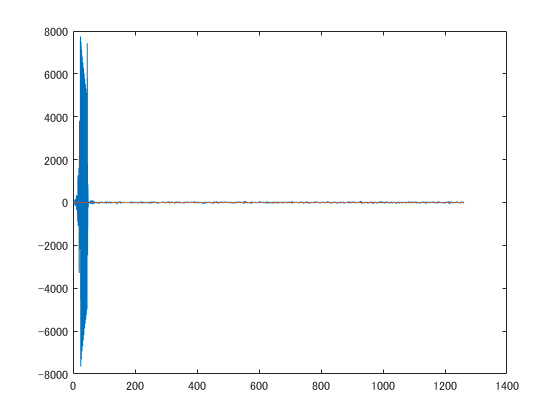


plot(yList);
hold on;
plot(rList);